## FDM

clear; clc;

a)

% Seed para a geração de números aleatórios
rng(123);
num_bits = 10000;

% Quatro sequências de bits pseudo-aleatórias
seq_bits1 = randi([0, 1], 1, num_bits);
seq_bits2 = randi([0, 1], 1, num_bits);
seq_bits3 = randi([0, 1], 1, num_bits);
seq_bits4 = randi([0, 1], 1, num_bits);

b)

% Parâmetros
Ts = 1 / 4000; % Duração do pulso (segundos)

Fa = 224000; % Frequência de amostragem (Hz)
app = Fa * Ts; % Amostras por pulso
t = 0:1/Fa:(app*num_bits/Fa-1/Fa);

sinal_2pam1 = repelem(2*seq_bits1-1, app)/sqrt(Ts);
sinal_2pam2 = repelem(2*seq_bits2-1, app)/sqrt(Ts);
sinal_2pam3 = repelem(2*seq_bits3-1, app)/sqrt(Ts);
sinal_2pam4 = repelem(2*seq_bits4-1, app)/sqrt(Ts);

% figure;
% plot(t, sinal_2pam1);
% title('Sinal 2-PAM - 1');
% xlabel('Tempo (s)');
% ylabel('Amplitude');
% xlim([0 3*app/Fa]);
% ylim([-80 80]);

c)

% Frequências das portadoras
f1 = 44000;
f2 = 52000;
f3 = 60000;
f4 = 68000;

% Modulação 2-PAM em banda passante
sinal_fdm1 = sinal_2pam1 .* cos(2 * pi * f1 * t) * sqrt(2);
sinal_fdm2 = sinal_2pam2 .* cos(2 * pi * f2 * t) * sqrt(2);
sinal_fdm3 = sinal_2pam3 .* cos(2 * pi * f3 * t) * sqrt(2);
sinal_fdm4 = sinal_2pam4 .* cos(2 * pi * f4 * t) * sqrt(2);

% figure;
% plot(t, sinal_fdm1);
% title('Sinal FDM 1');
% xlabel('Tempo (s)');
% ylabel('Amplitude');
% xlim([0 3*app/Fa]);
% ylim([-100 100]);

d)

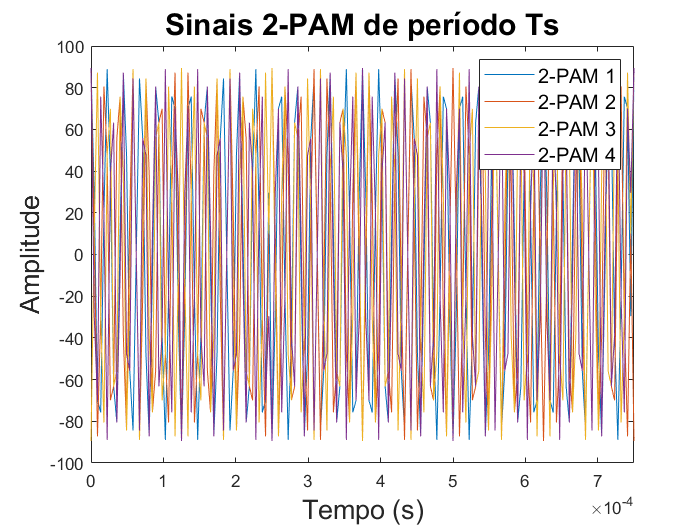

figure;
plot(t, sinal_fdm1, t, sinal_fdm2, t, sinal_fdm3, t, sinal_fdm4);
title('Sinais 2-PAM de período Ts', 'FontSize', 18);
xlabel('Tempo (s)', 'FontSize', 16);
ylabel('Amplitude', 'FontSize', 16);
legend('2-PAM 1','2-PAM 2','2-PAM 3','2-PAM 4', 'FontSize', 12);
xlim([0 3*app/Fa]);
ylim([-100 100]);
saveas(gcf, 'fdm_time.eps', 'epsc');

e)

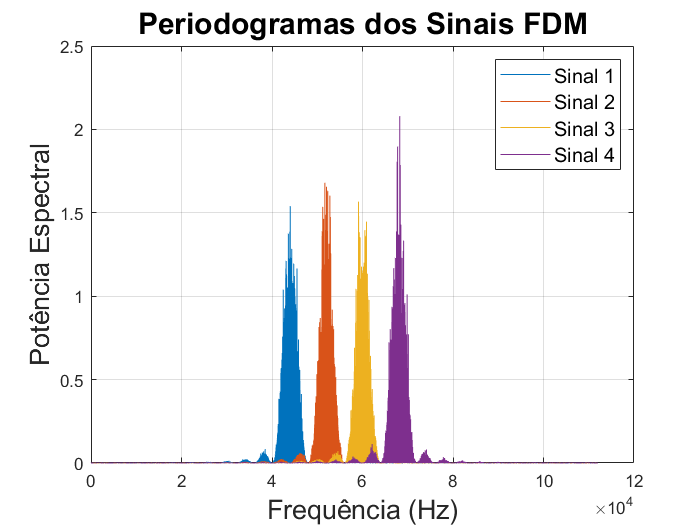

% Sinal 1
[Pxx1, Freq1] = periodogram(sinal_fdm1, [], [], Fa, 'centered', 'power');

% Sinal 2
[Pxx2, Freq2] = periodogram(sinal_fdm2, [], [], Fa, 'centered', 'power');

% Sinal 3
[Pxx3, Freq3] = periodogram(sinal_fdm3, [], [], Fa, 'centered', 'power');

% Sinal 4
[Pxx4, Freq4] = periodogram(sinal_fdm4, [], [], Fa, 'centered', 'power');

% Plot
figure;
plot(Freq1, Pxx1, Freq2, Pxx2, Freq3, Pxx3, Freq4, Pxx4);
xlim([0, 120000]);
xlabel('Frequência (Hz)', 'FontSize', 16);
ylabel('Potência Espectral', 'FontSize', 16);
legend('Sinal 1', 'Sinal 2', 'Sinal 3', 'Sinal 4', 'FontSize', 12);
title('Periodogramas dos Sinais FDM', 'FontSize', 18);
grid on;
saveas(gcf, 'fdm_freq.eps', 'epsc');

## TDM

clear; clc;

f)

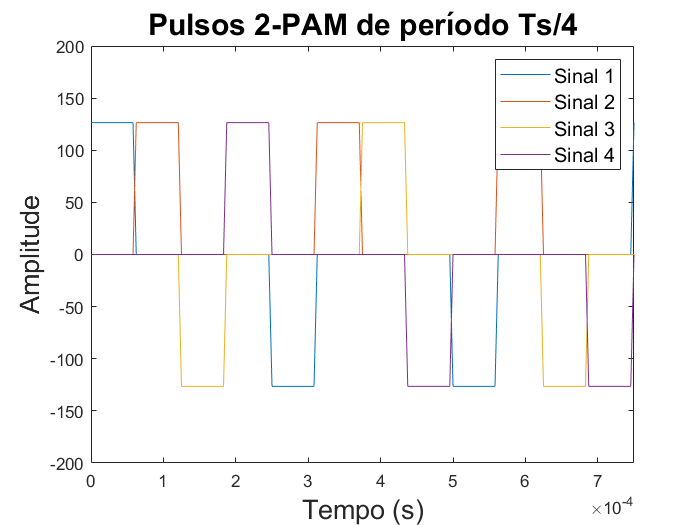

% Seed para a geração de números aleatórios
rng(123);
num_bits = 10000;

% Quatro sequências de bits pseudo-aleatórias
seq_bits1 = randi([0, 1], 1, num_bits);
seq_bits2 = randi([0, 1], 1, num_bits);
seq_bits3 = randi([0, 1], 1, num_bits);
seq_bits4 = randi([0, 1], 1, num_bits);
meios = ones(1,num_bits)/2;

m1 = [seq_bits1; meios; meios; meios];
m2 = [meios; seq_bits2; meios; meios];
m3 = [meios; meios; seq_bits3; meios];
m4 = [meios; meios; meios; seq_bits4];

% Parâmetros
Ts = (1 / 4000) / 4; % Duração do pulso (segundos)

Fa = 224000; % Frequência de amostragem (Hz)
app = Fa * Ts; % Amostras por pulso
t = 0:1/Fa:(4*app*num_bits/Fa-1/Fa);

sinal_2pam1 = repelem(2*m1(:)'-1, app)/sqrt(Ts);
sinal_2pam2 = repelem(2*m2(:)'-1, app)/sqrt(Ts);
sinal_2pam3 = repelem(2*m3(:)'-1, app)/sqrt(Ts);
sinal_2pam4 = repelem(2*m4(:)'-1, app)/sqrt(Ts);

figure;
plot(t, sinal_2pam1, t, sinal_2pam2, t, sinal_2pam3, t, sinal_2pam4);
title('Pulsos 2-PAM de período Ts/4', 'FontSize', 18);
xlabel('Tempo (s)', 'FontSize', 16);
ylabel('Amplitude', 'FontSize', 16);
legend('Sinal 1', 'Sinal 2', 'Sinal 3', 'Sinal 4', 'FontSize', 12);
xlim([0 4*3*app/Fa]);
ylim([-200 200]);
saveas(gcf, 'tdm_pulse.eps', 'epsc');

g)

% Frequências das portadoras
fc = 56000;

% Modulação TDM
sinal_tdm1 = sinal_2pam1 .* cos(2 * pi * fc * t) * sqrt(2);
sinal_tdm2 = sinal_2pam2 .* cos(2 * pi * fc * t) * sqrt(2);
sinal_tdm3 = sinal_2pam3 .* cos(2 * pi * fc * t) * sqrt(2);
sinal_tdm4 = sinal_2pam4 .* cos(2 * pi * fc * t) * sqrt(2);

% figure;
% plot(t, sinal_tdm1);
% title('Sinal FDM 1');
% xlabel('Tempo (s)');
% ylabel('Amplitude');
% xlim([0 4*3*app/Fa]);
% ylim([-250 250]);

h)

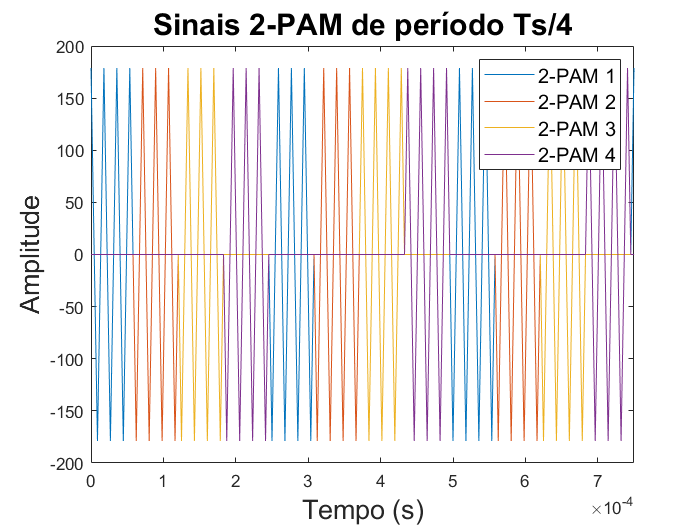

figure;
plot(t, sinal_tdm1, t, sinal_tdm2, t, sinal_tdm3, t, sinal_tdm4);
title('Sinais 2-PAM de período Ts/4', 'FontSize', 18);
xlabel('Tempo (s)', 'FontSize', 16);
ylabel('Amplitude', 'FontSize', 16);
legend('2-PAM 1','2-PAM 2','2-PAM 3','2-PAM 4', 'FontSize', 12);
xlim([0 4*3*app/Fa]);
ylim([-200 200]);
saveas(gcf, 'tdm_time.eps', 'epsc');

i)

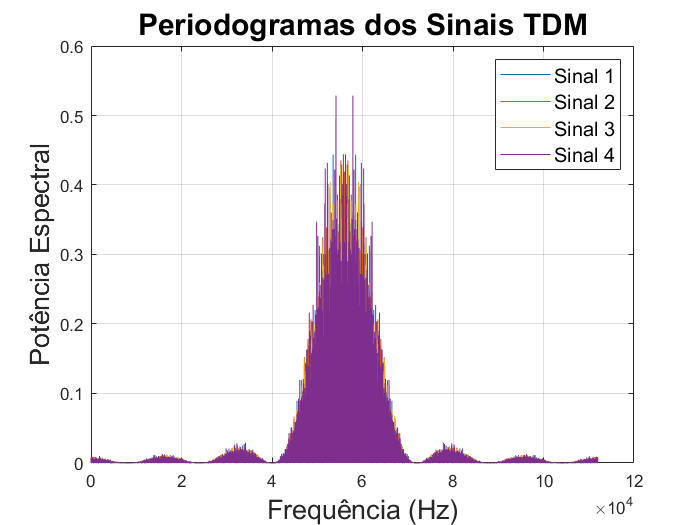

% Sinal 1
[Pxx1, Freq1] = periodogram(sinal_tdm1, [], [], Fa, 'centered', 'power');

% Sinal 2
[Pxx2, Freq2] = periodogram(sinal_tdm2, [], [], Fa, 'centered', 'power');

% Sinal 3
[Pxx3, Freq3] = periodogram(sinal_tdm3, [], [], Fa, 'centered', 'power');

% Sinal 4
[Pxx4, Freq4] = periodogram(sinal_tdm4, [], [], Fa, 'centered', 'power');

% Plot
figure;
plot(Freq1, Pxx1, Freq2, Pxx2, Freq3, Pxx3, Freq4, Pxx4);
xlim([0, 120000]);
xlabel('Frequência (Hz)', 'FontSize', 16);
ylabel('Potência Espectral', 'FontSize', 16);
legend('Sinal 1', 'Sinal 2', 'Sinal 3', 'Sinal 4', 'FontSize', 12);
title('Periodogramas dos Sinais TDM', 'FontSize', 18);
grid on;
saveas(gcf, 'tdm_freq.eps', 'epsc');

## CDM

clear; clc;

j)

% Seed para a geração de números aleatórios
rng(123);
num_bits = 10000;

% Quatro sequências de bits pseudo-aleatórias
seq_bits1 = randi([0, 1], 1, num_bits);
seq_bits2 = randi([0, 1], 1, num_bits);
seq_bits3 = randi([0, 1], 1, num_bits);
seq_bits4 = randi([0, 1], 1, num_bits);

% Parâmetros
Ts = (1 / 4000); % Duração do pulso (segundos)

Fa = 224000; % Frequência de amostragem (Hz)
app = Fa * Ts; % Amostras por pulso
t = 0:1/Fa:(app*num_bits/Fa-1/Fa);

sinal_2pam1 = repelem(2*seq_bits1-1, app)/sqrt(Ts);
sinal_2pam2 = repelem(2*seq_bits2-1, app)/sqrt(Ts);
sinal_2pam3 = repelem(2*seq_bits3-1, app)/sqrt(Ts);
sinal_2pam4 = repelem(2*seq_bits4-1, app)/sqrt(Ts);

% Sequências de espalhamento
seq1 = repmat(repelem(2*[0 0 1 1 1 0 1]-1, app/7),1,num_bits);
seq2 = repmat(repelem(2*[0 1 1 1 0 1 0]-1, app/7),1,num_bits);
seq3 = repmat(repelem(2*[1 1 1 0 1 0 0]-1, app/7),1,num_bits);
seq4 = repmat(repelem(2*[1 1 0 1 0 0 1]-1, app/7),1,num_bits);

sinal_seq1 = sinal_2pam1 .* seq1;
sinal_seq2 = sinal_2pam2 .* seq2;
sinal_seq3 = sinal_2pam3 .* seq3;
sinal_seq4 = sinal_2pam4 .* seq4;

% figure;
% plot(t, sinal_seq1);
% title('Sinais 2-PAM');
% xlabel('Tempo (s)');
% ylabel('Amplitude');
% legend('2-PAM 1','2-PAM 2','2-PAM 3','2-PAM 4');
% xlim([0 3*app/Fa]);
% ylim([-100 100]);

k)

% Frequências das portadoras
fc = 56000;

% Modulação CDM
sinal_cdm1 = sinal_seq1 .* cos(2 * pi * fc * t) * sqrt(2);
sinal_cdm2 = sinal_seq2 .* cos(2 * pi * fc * t) * sqrt(2);
sinal_cdm3 = sinal_seq3 .* cos(2 * pi * fc * t) * sqrt(2);
sinal_cdm4 = sinal_seq4 .* cos(2 * pi * fc * t) * sqrt(2);

% figure;
% plot(t, sinal_cdm1);
% title('Sinal CDM 1');
% xlabel('Tempo (s)');
% ylabel('Amplitude');
% xlim([0 3*app/Fa]);
% ylim([-250 250]);

l)

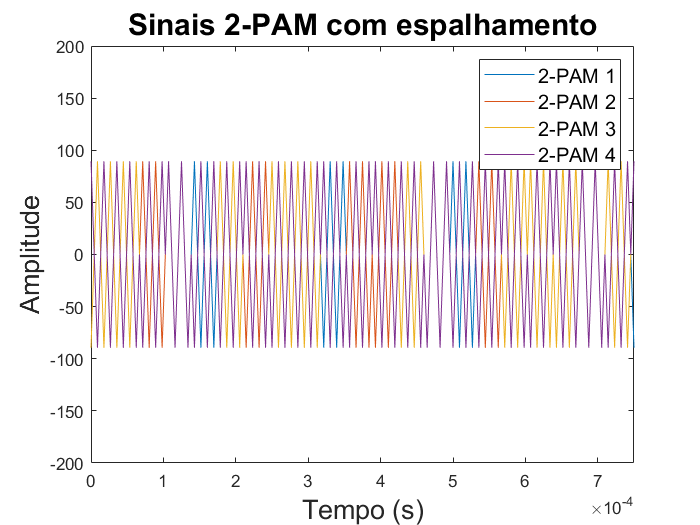

figure;
plot(t, sinal_cdm1, t, sinal_cdm2, t, sinal_cdm3, t, sinal_cdm4);
title('Sinais 2-PAM com espalhamento', 'FontSize', 18);
xlabel('Tempo (s)', 'FontSize', 16);
ylabel('Amplitude', 'FontSize', 16);
legend('2-PAM 1','2-PAM 2','2-PAM 3','2-PAM 4', 'FontSize', 12);
xlim([0 3*app/Fa]);
ylim([-200 200]);
saveas(gcf, 'cdm_time.eps', 'epsc');

m)

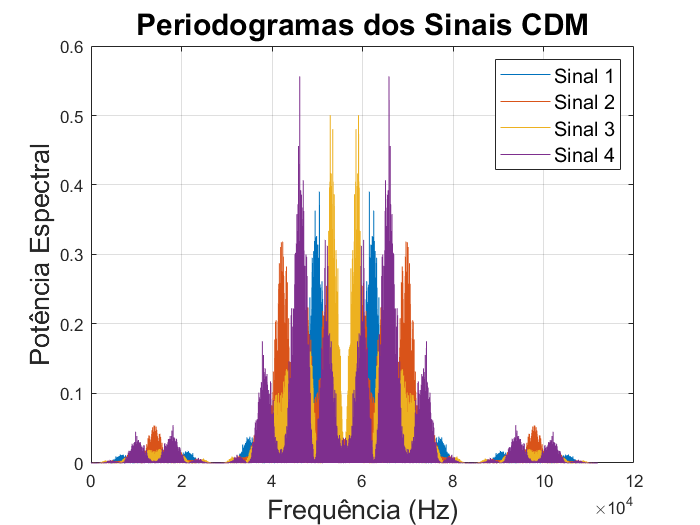

% Sinal 1
[Pxx1, Freq1] = periodogram(sinal_cdm1, [], [], Fa, 'centered', 'power');

% Sinal 2
[Pxx2, Freq2] = periodogram(sinal_cdm2, [], [], Fa, 'centered', 'power');

% Sinal 3
[Pxx3, Freq3] = periodogram(sinal_cdm3, [], [], Fa, 'centered', 'power');

% Sinal 4
[Pxx4, Freq4] = periodogram(sinal_cdm4, [], [], Fa, 'centered', 'power');

% Plot
figure;
plot(Freq1, Pxx1, Freq2, Pxx2, Freq3, Pxx3, Freq4, Pxx4);
xlim([0, 120000]);
xlabel('Frequência (Hz)', 'FontSize', 16);
ylabel('Potência Espectral', 'FontSize', 16);
legend('Sinal 1', 'Sinal 2', 'Sinal 3', 'Sinal 4', 'FontSize', 12);
title('Periodogramas dos Sinais CDM', 'FontSize', 18);
grid on;
saveas(gcf, 'cdm_freq.eps', 'epsc');

n)

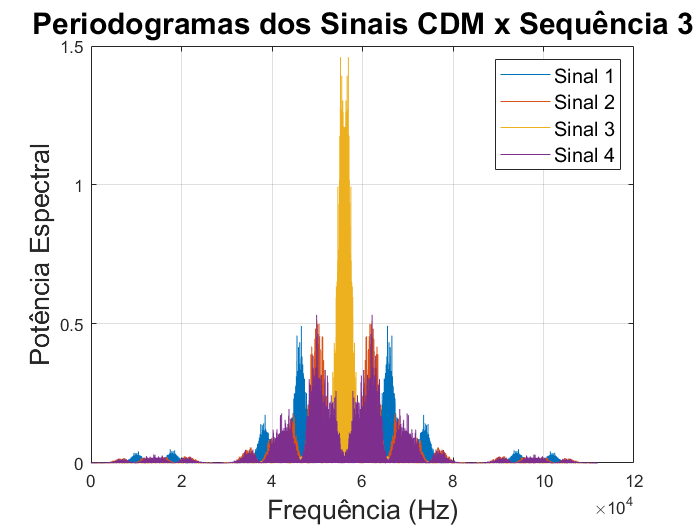

s = seq3;

% Sinal 1
[Pxx1, Freq1] = periodogram(sinal_cdm1 .* s, [], [], Fa, 'centered', 'power');

% Sinal 2
[Pxx2, Freq2] = periodogram(sinal_cdm2 .* s, [], [], Fa, 'centered', 'power');

% Sinal 3
[Pxx3, Freq3] = periodogram(sinal_cdm3 .* s, [], [], Fa, 'centered', 'power');

% Sinal 4
[Pxx4, Freq4] = periodogram(sinal_cdm4 .* s, [], [], Fa, 'centered', 'power');

% Plot
figure;
plot(Freq1, Pxx1, Freq2, Pxx2, Freq3, Pxx3, Freq4, Pxx4);
xlim([0, 120000]);
xlabel('Frequência (Hz)', 'FontSize', 16);
ylabel('Potência Espectral', 'FontSize', 16);
legend('Sinal 1', 'Sinal 2', 'Sinal 3', 'Sinal 4', 'FontSize', 12);
title('Periodogramas dos Sinais CDM x Sequência 3', 'FontSize', 18);
grid on;
saveas(gcf, 'cdm_seq3.eps', 'epsc');